% 创建 CRC 生成器对象，使用多项式 x^8 + x^2 + x + 1
crcGen = comm.CRCGenerator('Polynomial', [1,0,0,0,0,0,1,1,1]); % CRC-8 标准多项式
% 示例比特流数据（0 或 1 的行向量）
data = [1 0 1 1 0 0 1 1];  % 你可以替换为你自己的比特流

% 生成带有 CRC 的数据
encodedData = crcGen(data.');
disp('原始数据：');

原始数据：


disp(data);

     1     0     1     1     0     0     1     1



disp('添加了CRC的比特流：');

添加了CRC的比特流：


disp(encodedData.');

     1     0     1     1     0     0     1     1     0     0     0     1     0     0     0     0



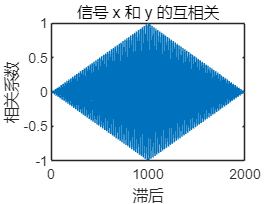

% 生成示例信号
t = 0:0.001:1;
x = sin(2*pi*50*t);          % 信号 x
y = sin(2*pi*50*t);  % 信号 y，相位延迟 pi/4

% 计算互相关
C = xcorr(x, y,'coeff');

% 绘制互相关结果
figure;
plot(C);
title('信号 x 和 y 的互相关');
xlabel('滞后');
ylabel('相关系数');